# **DEMO:    **7-dof car,  **Derivation** of the Transverse Vibration Equations of Motion

## Learning Objectives:

- Apply Newton's 2nd Law and derive the Transverse Vibration Equations of Motion for a 7-dof car model.

- A MODAL analysis is also performed. The Undamped modal frequencies and shapes are computed and visualized.

`Bradley Horton : 08-Aug-2021, bhorton@mathworks.com`

## Background:

Consider the system shown below - a **7 degree of freedom**(dof) model of a car. The model is focused on representing the TRANSVERSE vibrations of the Car Body and the 4 wheel+suspension assemblies.

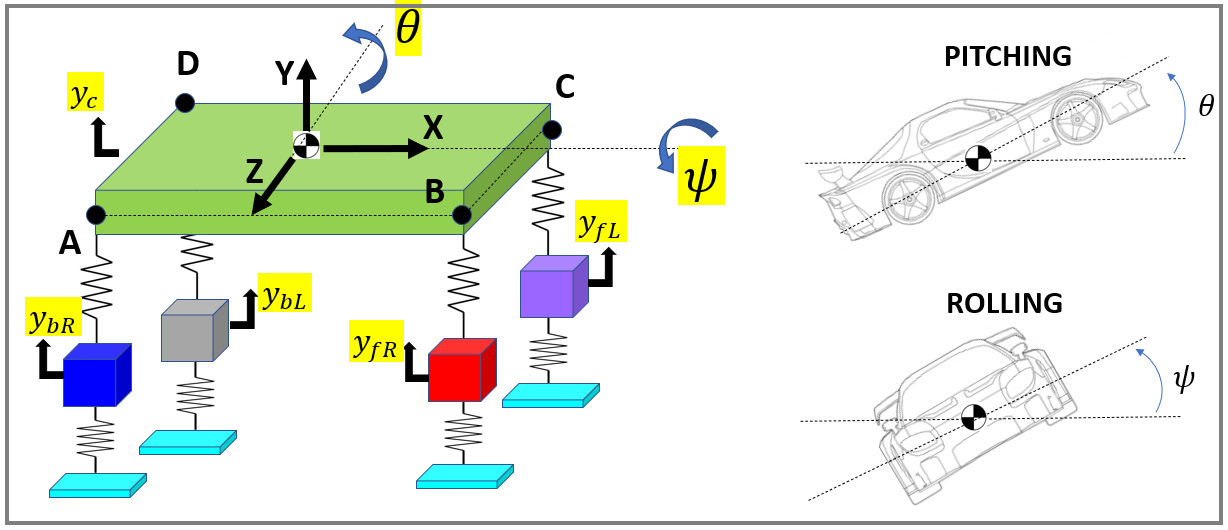

The **7 degree of freedom** of the model are:

-   $y_c$     :    Vertical displacement of car body Center of Mass

-   $\theta$      :    Pitching angular diplacement of the car body

-   $\psi$      :   Rolling angular diplacement of the car body

-   $y_{\textrm{bR}}$    :   Vertical displacement of the **back** RIGHT wheel+suspension assembly

-   $y_{\textrm{fR}}$     :   Vertical displacement of the *front* RIGHT wheel+suspension assembly

-   $y_{\textrm{bL}}$    :    Vertical displacement of the **back** LEFT wheel+suspension assembly

-   $y_{\textrm{fL}}$     :    Vertical displacement of the *front* LEFT wheel+suspension assembly

**NOTE:  **

- All of the Vertical displacements are measured from points corresponding to the car's "equilibrium" position

- In the diagram shown above each spring represents a stiffness and damping element connected in parallel

## Equation of motion derivation:

### Assumptions about the system:

To derive the TRANSVERSE equations of motion of the car system, we'll make the following assumptions about the system:

- **Small angles:   **We'll assume that the angular dof are small, such that $\sin \left(\theta \right)\approx \theta$ and $\sin \left(\psi \right)\approx \psi$

- We'll assume that a BODY fixed frame attached to the Car's Center of Mass(CoM) is alligned with the Principal axes of the body (ie: $\left.I_{\textrm{XY}} =I_{\textrm{XZ}} =I_{\textrm{YZ}} =0\right)$

- The angular velocity of the Car Body is $\omega =\left\lbrack \omega_X \;\;,\omega_Y \;\;,\omega_Z \right\rbrack =\left\lbrack \dot{\psi} \;\;,\;0\;\;,\;\dot{\theta} \right\rbrack$. **   NOTE: **  $\omega_Y ={\dot{\omega} }_Y \;=\;0$

Assumptions $1\to 3$ then allow us to simplify the generic Moment equation for a Rigid body to:

- 
$$\;M^B =I_G^B \;\ldotp {\dot{\omega} }_G^B \;\;\;+\;\;\omega \times \left(I_G^B \ldotp \omega_G^B \right)\;\;\;\Longrightarrow \;\;\;\;M^B =I_G^B \;\ldotp {\dot{\omega} }_G^B \;\;\;\;\Longrightarrow \;\;{\left\lbrack \begin{array}{c}
M_X \\
M_Z 
\end{array}\right\rbrack }^B \;\;=\;\;\left\lbrack \begin{array}{cc}
I_X  & 0\\
0 & I_Z 
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\ddot{\psi} \\
\ddot{\theta} 
\end{array}\right\rbrack$$


- see the file [`bh_7dof_CONCEPT_small_angles.mlx`](matlab:  edit bh_7dof_CONCEPT_small_angles.mlx)  for detailed summary on this

OK, so let's start by computing the forces acting on the Car body And the Wheel/suspension assemblies.  

- Assume all dof are moving in their positive direction

- Assume all springs are in Tension

The following diagram shows the car system in this general pose:

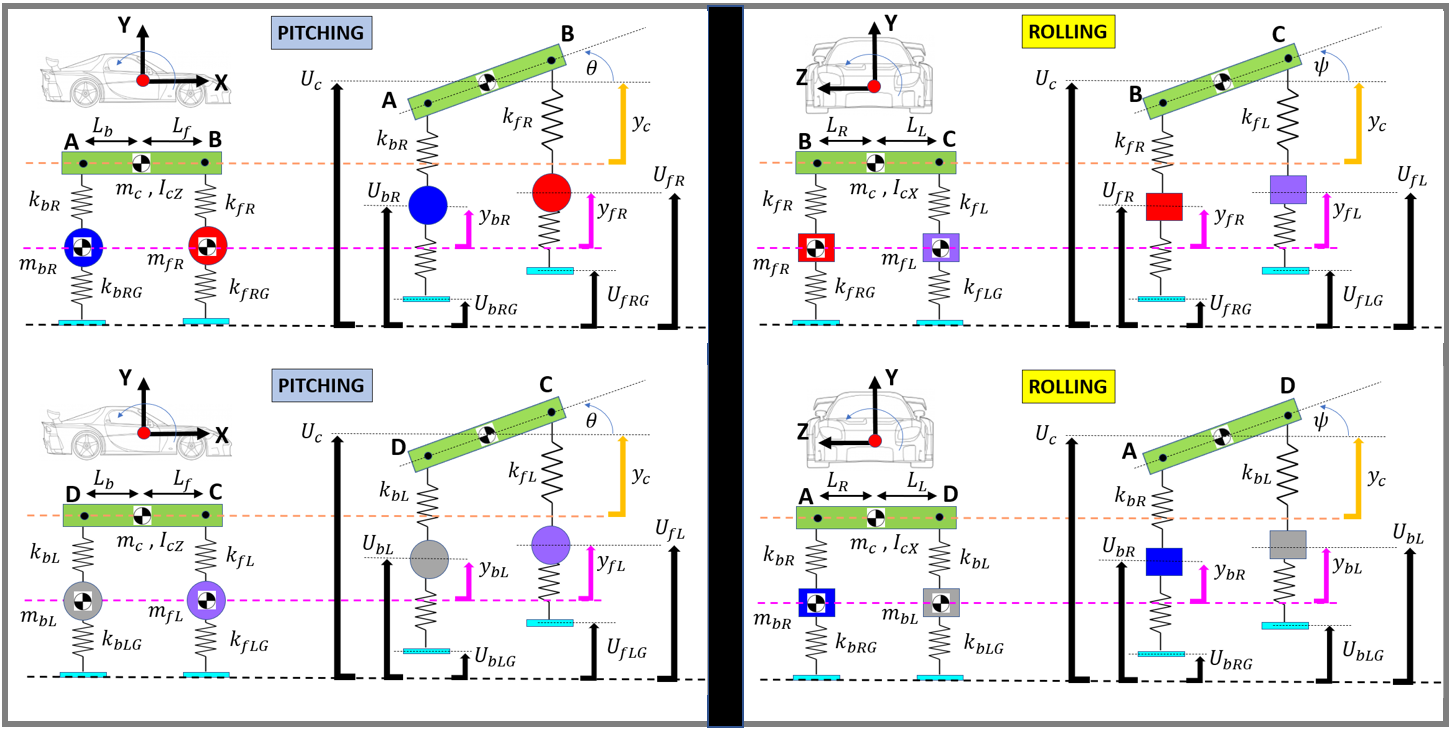

We'll use symbolic variable that match the diagram above:

syms L_b  L_f    L_R   L_L
syms  m_c    I_cZ    I_cX
syms  m_bR   m_fR    m_bL    m_fL
syms  k_bR   k_fR    k_bL    k_fL
syms  c_bR   c_fR    c_bL    c_fL
syms  k_bRG  k_fRG   k_bLG   k_fLG
syms  c_bRG  c_fRG   c_bLG   c_fLG

syms  y_c y_dot_c y_ddot_c
syms  y_dot_bR   y_dot_fR    y_dot_bL   y_dot_fL 
syms  y_ddot_bR  y_ddot_fR   y_ddot_bL  y_ddot_fL
syms  y_bR   y_fR    y_bL    y_fL   

syms  U_bRG  U_fRG   U_bLG   U_fLG  U_dot_bRG  U_dot_fRG   U_dot_bLG   U_dot_fLG

syms theta  theta_dot  theta_ddot
syms   psi    psi_dot    psi_ddot  

## Free Body Diagrams:

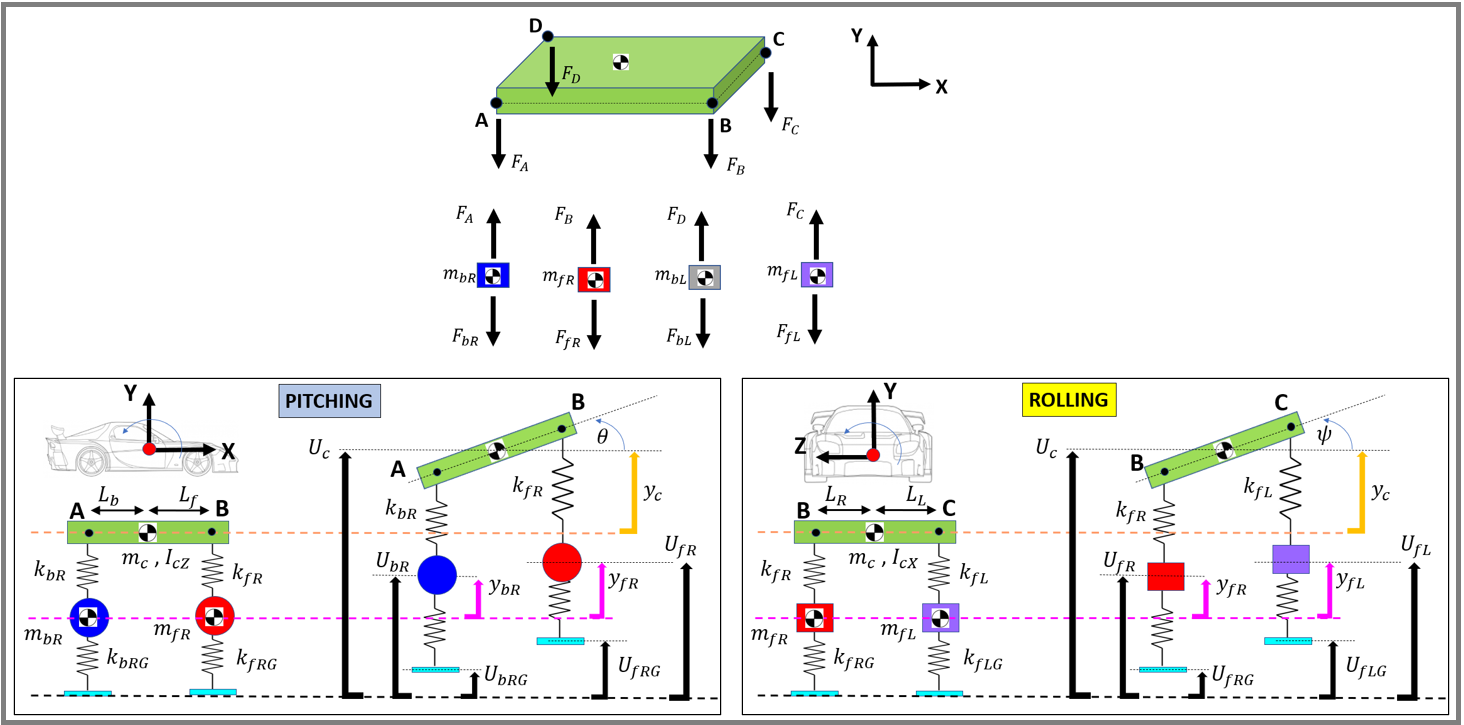

We'll define the forces shown in the above free body diagram 

F_A =   k_bR*(y_c - y_bR - L_b*theta - L_R*psi)   +   c_bR*(y_dot_c - y_dot_bR - L_b*theta_dot - L_R*psi_dot);
F_D =   k_bL*(y_c - y_bL - L_b*theta + L_L*psi)   +   c_bL*(y_dot_c - y_dot_bL - L_b*theta_dot + L_L*psi_dot);
F_B =   k_fR*(y_c - y_fR + L_f*theta - L_R*psi)   +   c_fR*(y_dot_c - y_dot_fR + L_f*theta_dot - L_R*psi_dot);
F_C =   k_fL*(y_c - y_fL + L_f*theta + L_L*psi)   +   c_fL*(y_dot_c - y_dot_fL + L_f*theta_dot + L_L*psi_dot);

Also define the TYRE spring forces $\left(F_{\textrm{bR}} \;\;\;,\;F_{\textrm{fR}} \;\;\;,\;F_{\textrm{bL}} \;\;\;,\;F_{\textrm{fL}} \right)$ acting on each Wheel/suspension assembly:

F_BLUE_bR   = k_bRG*(y_bR - U_bRG) + c_bRG*(y_dot_bR - U_dot_bRG);
F_RED_fR    = k_fRG*(y_fR - U_fRG) + c_fRG*(y_dot_fR - U_dot_fRG);
F_GREY_bL   = k_bLG*(y_bL - U_bLG) + c_bLG*(y_dot_bL - U_dot_bLG);
F_PURPLE_fL = k_fLG*(y_fL - U_fLG) + c_fLG*(y_dot_fL - U_dot_fLG);

## 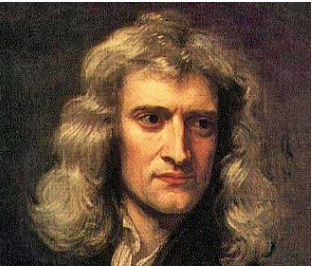  Apply Newton's 2nd Law

From our Free Body diagrams we can now apply Newton's 2nd Law, ie:

-    $m\ldotp \ddot{y} \;=\;\sum_i F_i$    and     $I\ldotp \ddot{\theta} \;=\sum_i \tau_i \;\;$

Consider the **FORCE** equation for each **Wheel/suspension assembly**:

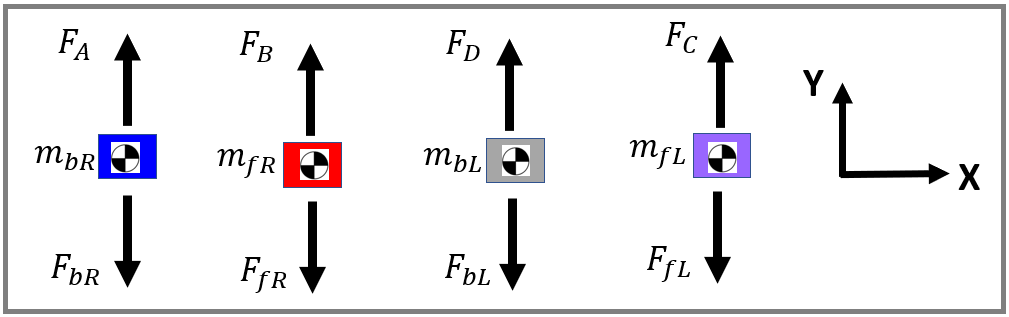

EQ_BLUE_mbR   = m_bR * y_ddot_bR ==  -1*F_BLUE_bR   + F_A;
EQ_RED_mfR    = m_fR * y_ddot_fR ==  -1*F_RED_fR    + F_B;
EQ_GREY_mbL   = m_bL * y_ddot_bL ==  -1*F_GREY_bL   + F_D;
EQ_PURPLE_mfL = m_fL * y_ddot_fL ==  -1*F_PURPLE_fL + F_C;

Consider the **FORCE** equation for the **GREEN Car Body**:

EQ_GREEN_mc   = m_c  * y_ddot_c  == -1*( F_A  +  F_B  +  F_C  +  F_D );

Now consider the pitch and roll **MOMENT** equations for the **GREEN Car body:**

-  **RECALL** our small angle assumptions, eg:   [`bh_7dof_CONCEPT_small_angles.mlx`](matlab:  edit bh_7dof_CONCEPT_small_angles.mlx) 

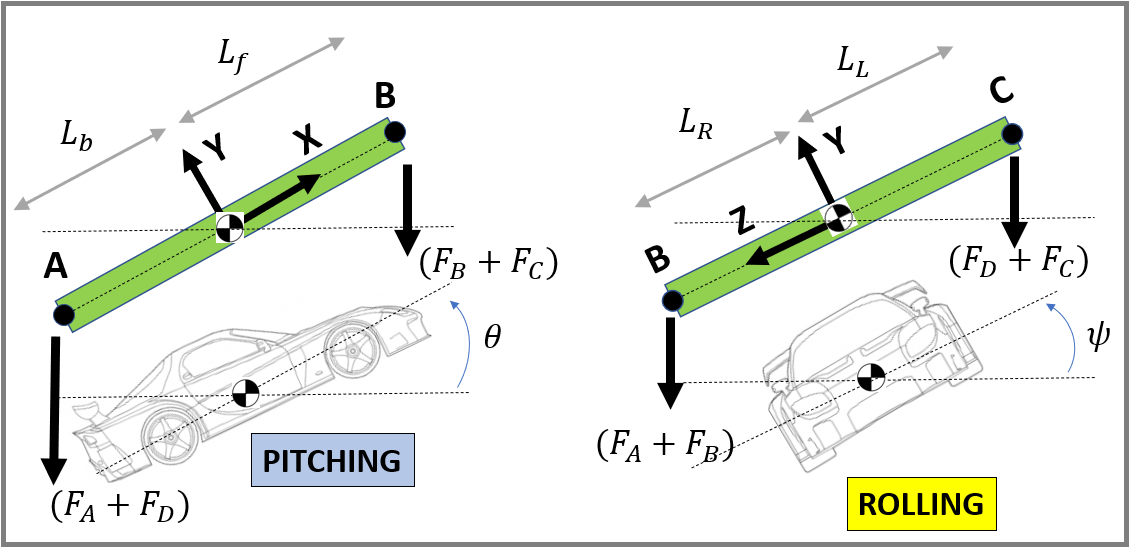

The PITCH moment equation for the GREEN Car Body:

EQ_GREEN_IcZ  = I_cZ * theta_ddot ==    (F_A + F_D  )*L_b  -  (F_B + F_C)*L_f;

The ROLL moment equation for the GREEN Car Body:

EQ_GREEN_IcX  = I_cX * psi_ddot   == (F_B + F_A)*L_R  - (F_C + F_D)*L_L;

### Summary:

The 7 equations of motion look like this:

:  Our Small angle assumption results in Linear ODEs ..... which means we can write them in the familiar form $M\ldotp \ddot{X} \;+\;C\ldotp \dot{X} \;+\;K\ldotp X\;=\;F$ 

my_sys_EQ = [ EQ_GREEN_mc   ;
              EQ_GREEN_IcZ  ;
              EQ_GREEN_IcX  ;     
              EQ_BLUE_mbR   ;
              EQ_RED_mfR    ;
              EQ_GREY_mbL   ;
              EQ_PURPLE_mfL ;  ]

Also, recall our 7 degrees of freedom.  We'll define them in this order 

-  
$$X^T =\left\lbrack \begin{array}{ccccccc}
y_c  & \theta  & \psi  & y_{\textrm{bR}}  & y_{\textrm{fR}}  & y_{\textrm{bL}}  & y_{\textrm{fL}} 
\end{array}\right\rbrack$$


my_7dof_sym_list = [y_c,  theta,  psi,    y_bR,  y_fR,  y_bL,  y_fL]

$$my\_7dof\_sym\_list = \left(\begin{array}{ccccccc} y_{c} & \theta & \psi & y_{\mathrm{bR}} & y_{\mathrm{fR}} & y_{\mathrm{bL}} & y_{\mathrm{fL}} \end{array}\right)$$


my_7dof_str_list = string(my_7dof_sym_list);

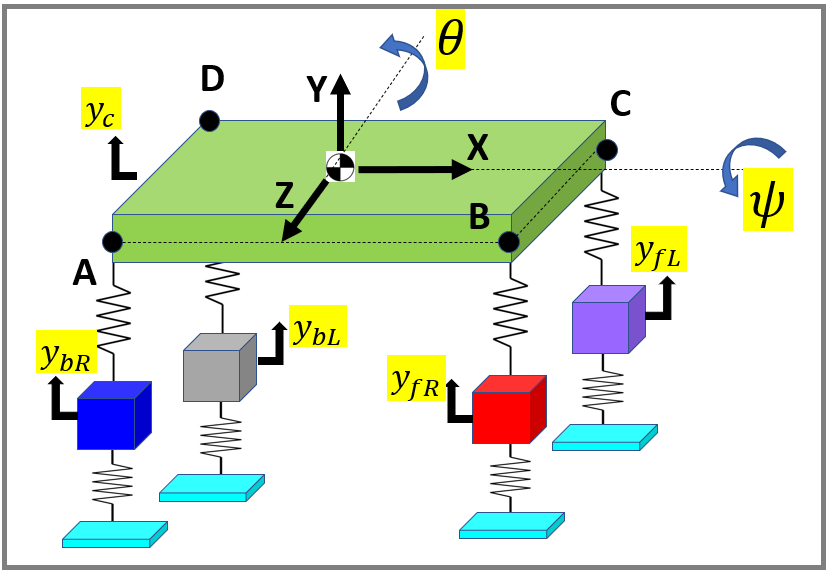

### Now collect equations and extract $M,C,K,F$:

We know that our system equations of motion can be written in the form:

- $M\ldotp \ddot{X} \;+\;C\ldotp \dot{X} \;+\;K\ldotp X\;=\;F$     where   $X\in R^{\;7\times 1}$     and       $X^T =\left\lbrack \begin{array}{ccccccc}
y_c  & \theta  & \psi  & y_{\textrm{bR}}  & y_{\textrm{fR}}  & y_{\textrm{bL}}  & y_{\textrm{fL}} 
\end{array}\right\rbrack$

We can rewrite this equation as a "mega" equation of the form:

- $\left\lbrack \begin{array}{ccc}
M & C & K
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
\ddot{X} \\
\dot{X} \\
X
\end{array}\right\rbrack =\;F$     $\Longrightarrow$     $A\;\ldotp Z=b$      where   $Z\in R^{\;21\times 1}$   and   $A\;=\left\lbrack M\;\;C\;\;K\right\rbrack \;\in R^{\;7\times 21}$

The [`equationsToMatrix()`](matlab:  web(fullfile(docroot, 'symbolic/sym.equationstomatrix.html'))) function will rearrange our 7 equations of motion into this $A\;\ldotp Z=b$  form:

my_Z_vars = [ y_ddot_c,  theta_ddot,  psi_ddot,  y_ddot_bR,  y_ddot_fR,  y_ddot_bL,  y_ddot_fL, ...
               y_dot_c,  theta_dot,   psi_dot,    y_dot_bR,   y_dot_fR,   y_dot_bL,   y_dot_fL, ...
                   y_c,  theta,       psi,            y_bR,       y_fR,       y_bL,       y_fL  ];   
    
[A, b]    = equationsToMatrix(my_sys_EQ, my_Z_vars)    

$$b = \left(\begin{array}{c} 0\\ 0\\ 0\\ {\dot{U}}_{\mathrm{bRG}}\,c_{\mathrm{bRG}}+U_{\mathrm{bRG}}\,k_{\mathrm{bRG}}\\ {\dot{U}}_{\mathrm{fRG}}\,c_{\mathrm{fRG}}+U_{\mathrm{fRG}}\,k_{\mathrm{fRG}}\\ {\dot{U}}_{\mathrm{bLG}}\,c_{\mathrm{bLG}}+U_{\mathrm{bLG}}\,k_{\mathrm{bLG}}\\ {\dot{U}}_{\mathrm{fLG}}\,c_{\mathrm{fLG}}+U_{\mathrm{fLG}}\,k_{\mathrm{fLG}} \end{array}\right)$$

Great, so now we can finally "extract" our classic $M,C,K,F$ matrices:

M_mat = A(:,  1:7)

$$M\_mat = \left(\begin{array}{ccccccc} m_{c} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & I_{\mathrm{cZ}} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & I_{\mathrm{cX}} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & m_{\mathrm{bR}} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & m_{\mathrm{fR}} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & m_{\mathrm{bL}} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & m_{\mathrm{fL}} \end{array}\right)$$

C_mat = A(:,  8:14)

$$C\_mat = \left(\begin{array}{ccccccc} c_{\mathrm{bL}}+c_{\mathrm{bR}}+c_{\mathrm{fL}}+c_{\mathrm{fR}} & L_{f}\,c_{\mathrm{fL}}-L_{b}\,c_{\mathrm{bR}}-L_{b}\,c_{\mathrm{bL}}+L_{f}\,c_{\mathrm{fR}} & L_{L}\,c_{\mathrm{bL}}+L_{L}\,c_{\mathrm{fL}}-L_{R}\,c_{\mathrm{bR}}-L_{R}\,c_{\mathrm{fR}} & -c_{\mathrm{bR}} & -c_{\mathrm{fR}} & -c_{\mathrm{bL}} & -c_{\mathrm{fL}}\\ L_{f}\,\left(c_{\mathrm{fL}}+c_{\mathrm{fR}}\right)-L_{b}\,\left(c_{\mathrm{bL}}+c_{\mathrm{bR}}\right) & L_{b}\,\left(L_{b}\,c_{\mathrm{bL}}+L_{b}\,c_{\mathrm{bR}}\right)+L_{f}\,\left(L_{f}\,c_{\mathrm{fL}}+L_{f}\,c_{\mathrm{fR}}\right) & L_{f}\,\left(L_{L}\,c_{\mathrm{fL}}-L_{R}\,c_{\mathrm{fR}}\right)-L_{b}\,\left(L_{L}\,c_{\mathrm{bL}}-L_{R}\,c_{\mathrm{bR}}\right) & L_{b}\,c_{\mathrm{bR}} & -L_{f}\,c_{\mathrm{fR}} & L_{b}\,c_{\mathrm{bL}} & -L_{f}\,c_{\mathrm{fL}}\\ L_{L}\,\left(c_{\mathrm{bL}}+c_{\mathrm{fL}}\right)-L_{R}\,\left(c_{\mathrm{bR}}+c_{\mathrm{fR}}\right) & L_{R}\,\left(L_{b}\,c_{\mathrm{bR}}-L_{f}\,c_{\mathrm{fR}}\right)-L_{L}\,\left(L_{b}\,c_{\mathrm{bL}}-L_{f}\,c_{\mathrm{fL}}\right) & L_{L}\,\left(L_{L}\,c_{\mathrm{bL}}+L_{L}\,c_{\mathrm{fL}}\right)+L_{R}\,\left(L_{R}\,c_{\mathrm{bR}}+L_{R}\,c_{\mathrm{fR}}\right) & L_{R}\,c_{\mathrm{bR}} & L_{R}\,c_{\mathrm{fR}} & -L_{L}\,c_{\mathrm{bL}} & -L_{L}\,c_{\mathrm{fL}}\\ -c_{\mathrm{bR}} & L_{b}\,c_{\mathrm{bR}} & L_{R}\,c_{\mathrm{bR}} & c_{\mathrm{bR}}+c_{\mathrm{bRG}} & 0 & 0 & 0\\ -c_{\mathrm{fR}} & -L_{f}\,c_{\mathrm{fR}} & L_{R}\,c_{\mathrm{fR}} & 0 & c_{\mathrm{fR}}+c_{\mathrm{fRG}} & 0 & 0\\ -c_{\mathrm{bL}} & L_{b}\,c_{\mathrm{bL}} & -L_{L}\,c_{\mathrm{bL}} & 0 & 0 & c_{\mathrm{bL}}+c_{\mathrm{bLG}} & 0\\ -c_{\mathrm{fL}} & -L_{f}\,c_{\mathrm{fL}} & -L_{L}\,c_{\mathrm{fL}} & 0 & 0 & 0 & c_{\mathrm{fL}}+c_{\mathrm{fLG}} \end{array}\right)$$

K_mat = A(:, 15:21)

$$K\_mat = \left(\begin{array}{ccccccc} k_{\mathrm{bL}}+k_{\mathrm{bR}}+k_{\mathrm{fL}}+k_{\mathrm{fR}} & L_{f}\,k_{\mathrm{fL}}-L_{b}\,k_{\mathrm{bR}}-L_{b}\,k_{\mathrm{bL}}+L_{f}\,k_{\mathrm{fR}} & L_{L}\,k_{\mathrm{bL}}+L_{L}\,k_{\mathrm{fL}}-L_{R}\,k_{\mathrm{bR}}-L_{R}\,k_{\mathrm{fR}} & -k_{\mathrm{bR}} & -k_{\mathrm{fR}} & -k_{\mathrm{bL}} & -k_{\mathrm{fL}}\\ L_{f}\,\left(k_{\mathrm{fL}}+k_{\mathrm{fR}}\right)-L_{b}\,\left(k_{\mathrm{bL}}+k_{\mathrm{bR}}\right) & L_{b}\,\left(L_{b}\,k_{\mathrm{bL}}+L_{b}\,k_{\mathrm{bR}}\right)+L_{f}\,\left(L_{f}\,k_{\mathrm{fL}}+L_{f}\,k_{\mathrm{fR}}\right) & L_{f}\,\left(L_{L}\,k_{\mathrm{fL}}-L_{R}\,k_{\mathrm{fR}}\right)-L_{b}\,\left(L_{L}\,k_{\mathrm{bL}}-L_{R}\,k_{\mathrm{bR}}\right) & L_{b}\,k_{\mathrm{bR}} & -L_{f}\,k_{\mathrm{fR}} & L_{b}\,k_{\mathrm{bL}} & -L_{f}\,k_{\mathrm{fL}}\\ L_{L}\,\left(k_{\mathrm{bL}}+k_{\mathrm{fL}}\right)-L_{R}\,\left(k_{\mathrm{bR}}+k_{\mathrm{fR}}\right) & L_{R}\,\left(L_{b}\,k_{\mathrm{bR}}-L_{f}\,k_{\mathrm{fR}}\right)-L_{L}\,\left(L_{b}\,k_{\mathrm{bL}}-L_{f}\,k_{\mathrm{fL}}\right) & L_{L}\,\left(L_{L}\,k_{\mathrm{bL}}+L_{L}\,k_{\mathrm{fL}}\right)+L_{R}\,\left(L_{R}\,k_{\mathrm{bR}}+L_{R}\,k_{\mathrm{fR}}\right) & L_{R}\,k_{\mathrm{bR}} & L_{R}\,k_{\mathrm{fR}} & -L_{L}\,k_{\mathrm{bL}} & -L_{L}\,k_{\mathrm{fL}}\\ -k_{\mathrm{bR}} & L_{b}\,k_{\mathrm{bR}} & L_{R}\,k_{\mathrm{bR}} & k_{\mathrm{bR}}+k_{\mathrm{bRG}} & 0 & 0 & 0\\ -k_{\mathrm{fR}} & -L_{f}\,k_{\mathrm{fR}} & L_{R}\,k_{\mathrm{fR}} & 0 & k_{\mathrm{fR}}+k_{\mathrm{fRG}} & 0 & 0\\ -k_{\mathrm{bL}} & L_{b}\,k_{\mathrm{bL}} & -L_{L}\,k_{\mathrm{bL}} & 0 & 0 & k_{\mathrm{bL}}+k_{\mathrm{bLG}} & 0\\ -k_{\mathrm{fL}} & -L_{f}\,k_{\mathrm{fL}} & -L_{L}\,k_{\mathrm{fL}} & 0 & 0 & 0 & k_{\mathrm{fL}}+k_{\mathrm{fLG}} \end{array}\right)$$

F_col = b

$$F\_col = \left(\begin{array}{c} 0\\ 0\\ 0\\ {\dot{U}}_{\mathrm{bRG}}\,c_{\mathrm{bRG}}+U_{\mathrm{bRG}}\,k_{\mathrm{bRG}}\\ {\dot{U}}_{\mathrm{fRG}}\,c_{\mathrm{fRG}}+U_{\mathrm{fRG}}\,k_{\mathrm{fRG}}\\ {\dot{U}}_{\mathrm{bLG}}\,c_{\mathrm{bLG}}+U_{\mathrm{bLG}}\,k_{\mathrm{bLG}}\\ {\dot{U}}_{\mathrm{fLG}}\,c_{\mathrm{fLG}}+U_{\mathrm{fLG}}\,k_{\mathrm{fLG}} \end{array}\right)$$

## Convert to Simulink blocks

Let's convert our $M,C,K,F$ matrices into Simulink blocks.

-  **NOTE: ** We'll discuss these further in the section called **Next Steps**.

tf_i_should_create_SL_blocks = true;

if(tf_i_should_create_SL_blocks)
    MODEL_NAME = 'bh_tmp_model_WILL_BE_DELETED';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
    purple_str = '[0.6, 0.6, 1]';
    %-------------------------------------------------------
    % Create a block that computes A and b
    matlabFunctionBlock( [MODEL_NAME,'/my_M_mat'], M_mat);
    matlabFunctionBlock( [MODEL_NAME,'/my_C_mat'], C_mat);    
    matlabFunctionBlock( [MODEL_NAME,'/my_K_mat'], K_mat);   
    matlabFunctionBlock( [MODEL_NAME,'/my_F_col'], F_col);
    
    % make the blocks a YELLOW color
    set_param([MODEL_NAME,'/my_M_mat'],'BackgroundColor',purple_str,'Position', [-325   262  -190   478]);
    set_param([MODEL_NAME,'/my_C_mat'],'BackgroundColor',purple_str,'Position', [45   -46   180   271]);    
    set_param([MODEL_NAME,'/my_K_mat'],'BackgroundColor',purple_str,'Position', [45   308   180   617]);
    set_param([MODEL_NAME,'/my_F_col'],'BackgroundColor',purple_str,'Position', [610     2   735   563]);    
end       

Unrecognized function or variable 'M_mat'.

## Modal Analysis

Before we simulate(aka solve) our derived equations of motion, let's do a MODAL analysis of the system.  Consider the **UNdamped** homogeneous system:

- $M\ldotp \ddot{X} \;+\;K\ldotp X\;=0$  where $X\;\in R^{\;N\times 1}$

And let's look for a harmonic solution of the form:

- 
$$X\left(t\right)=v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$\dot{X} \left(t\right)=\;\;\;\;\;\;\;\;\;\;i\ldotp \omega \;\ldotp X\left(t\right)$$


- 
$$\ddot{X} \left(t\right)=\;\;\;-1\ldotp \omega^2 \ldotp X\left(t\right)\;$$


Then our ODE becomes:

- 
$$\left\lbrack -M\ldotp \omega^2 \;\;+\;\;K\right\rbrack \ldotp X\left(t\right)\;=\;0$$


- 
$$K\ldotp X\left(t\right)=M\ldotp X\left(t\right)\ldotp \omega^2$$


- 
$$M^{-1} \ldotp K\ldotp X\left(t\right)=\omega^2 \ldotp X\left(t\right)$$


- 
$$M^{-1} \ldotp K\ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t} =\omega^2 \ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$M^{-1} \ldotp K\ldotp v=\omega^2 \ldotp v$$


- $A\ldotp v=\lambda \;\ldotp v$       where  $\lambda =\omega^2$  and $A=M^{-1} \ldotp K$

The last equation is the **classic Eigenvalue problem**.  So let's solve this in MATLAB using the [`eig()`](matlab: doc eig) function:

First we need some NUMERIC values for our car's parameters(ie: mass, damping, stiffness).

- These numeric parameters are in an EXCEL file [`bh_7dof_car_database.xlsx`](matlab:  winopen( "bh_7dof_car_database.xlsx"))

OBJ_car_params =  bh_7dof_car_database_CLS("bh_7dof_car_database.xlsx","PARAMS_SET_A", "IC_SET_A");
OBJ_car_params.car_tab

ans = 29×4 table
              Name       Value      Units                     Description                
             _______    _______    ________    __________________________________________

    m_c      "m_c"         1500    "kg"        "Mass of car body"                        
    I_cZ     "I_cZ"        1000    "kg.m^2"    "Inertia (Z-axis) of car body"            
    I_cX     "I_cX"         600    "kg.m^2"    "Inertia (X-axis) of car body"            
    m_bR     "m_bR"          80    "kg"        "Mass of back RIGHT wheel and suspension" 
    m_fR     "m_fR"         100    "kg"        "Mass of front RIGHT wheel and suspension"
    m_bL     "m_bL"          80    "kg"        "Mass of back LEFT wheel and suspension"  
    m_fL 

Let's now populate our system $M,C,K$matrices

- This is done in a subfunction `LOC_get_MCK` at the bottom of this script 

[M_num, C_num, K_num ] = LOC_get_MCK(M_mat, C_mat, K_mat, OBJ_car_params);

whos  M_num  C_num  K_num

  Name       Size            Bytes  Class     Attributes

  C_num      7x7               392  double              
  K_num      7x7               392  double              
  M_num      7x7               392  double              



 Now solve the classic Eigenvalue problem using MATLAB's [`eig()`](matlab: doc eig) function:

A            = inv(M_num) * K_num;
[eVec, eVal] = eig(A)

eVec =     0.0093   -0.0117    0.9548   -0.1212    0.0000    0.0000   -0.0000
   -0.0251   -0.0204    0.1863    0.9271   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000   -0.0000   -0.9808   -0.0189   -0.0232
   -0.7068    0.0141    0.0783   -0.2190    0.0970   -0.7069    0.0112
    0.0088    0.7068    0.1437    0.1222    0.0979   -0.0071   -0.7068
   -0.7068    0.0141    0.0783   -0.2190   -0.0970    0.7069   -0.0112
    0.0088    0.7068    0.1437    0.1222   -0.0979    0.0071    0.7068


eVal = 1.0e+03 *

    1.5763         0         0         0         0         0         0
         0    1.2574         0         0         0         0         0
         0         0    0.0331         0         0         0         0
         0         0         0    0.1107         0         0         0
         0         0         0         0    0.0553         0         0
         0         0         0         0         0    1.5665         0
         0         0         0         0         0         0    1.2539



whos eVec   eVal

  Name      Size            Bytes  Class     Attributes

  eVal      7x7               392  double              
  eVec      7x7               392  double              



**Sort the eigenvector columns based on the ascending order of the eigenvalues:**

[~,ind] = sort( diag(eVal) );

eVec = eVec(:, ind);
eVal = eVal(:, ind);

Let's normalise the eigenvectors such that:  

-   
$$I\;\;={\;\;V}^T \ldotp M\ldotp V$$


- 
$$\;\Omega^{2\;} =\;\;V^T \ldotp K\ldotp V$$


tmp         = eVec.' * M_num * eVec;
tmp_row     =  diag(tmp)';
eVec_PHI    = eVec ./ sqrt( tmp_row );

Im_mat      = eVec_PHI.' * M_num * eVec_PHI

Im_mat =     1.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0000    1.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000    1.0000    0.0000   -0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000    0.0000    1.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000    1.0000    0.0000
   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    1.0000


w2_mat      = eVec_PHI.' * K_num * eVec_PHI

w2_mat = 1.0e+03 *

    0.0331    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0000    0.0553   -0.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.1107    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000    1.2539    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    1.2574   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000    1.5665    0.0000
   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.5763


#### Great, so let's summarise what we have. 

Our UNdamped frequencies of vibration are:   $\omega \;\;\;\left\lbrack \frac{\textrm{rad}}{\sec }\right\rbrack$:

w_list = sqrt( diag(w2_mat) );
w_table = array2table( [w_list, w_list/(2*pi)], "VariableNames", {'w_radpersec', 'f_Hz'}  )

w_table = 7×2 table
    w_radpersec     f_Hz  
    ___________    _______

      5.7568       0.91623
      7.4366        1.1836
      10.519        1.6742
      35.411        5.6358
      35.459        5.6435
      39.579        6.2992
      39.702        6.3188


Our MODE shapes are the columns of the matrix:

eVec_PHI

eVec_PHI =     0.0255    0.0000   -0.0041   -0.0000   -0.0012    0.0000    0.0010
    0.0050   -0.0000    0.0310   -0.0000   -0.0020   -0.0000   -0.0028
   -0.0000   -0.0407   -0.0000   -0.0023    0.0000   -0.0021    0.0000
    0.0021    0.0040   -0.0073    0.0011    0.0014   -0.0789   -0.0787
    0.0038    0.0041    0.0041   -0.0706    0.0705   -0.0008    0.0010
    0.0021   -0.0040   -0.0073   -0.0011    0.0014    0.0789   -0.0787
    0.0038   -0.0041    0.0041    0.0706    0.0705    0.0008    0.0010


We can visualize the mode shapes.  

- For visualiztion, let's normalise each mode shape column by it's largest absolute value ... so that we can see which DOF makes the dominant contribution in each mode 

NUM_DOF             =   size(eVec_PHI,1);
MAX_NORM_eVec_PHI   = eVec_PHI ./ repmat(max(abs(eVec_PHI)), NUM_DOF, 1);

Create a table of our MAX normalised Mode shapes:

mode_table = array2table( MAX_NORM_eVec_PHI, ...
                          "VariableNames",  "MODE_"+[1:7], ...
                          "RowNames"     ,  my_7dof_str_list ) 

mode_table = 7×7 table
               MODE_1         MODE_2         MODE_3         MODE_4        MODE_5        MODE_6         MODE_7  
             ___________    ___________    ___________    ___________    _________    ___________    __________

    y_c                1     6.1573e-16       -0.13069    -6.2694e-17    -0.016489     2.1503e-16      0.013118
    theta        0.19516    -1.3911e-15              1    -1.7497e-17    -0.028843    -3.6945e-16     -0.035544
    psi      -4.0517e-17             -1    -2.3433e-16      -0.032853    1.048e-16      -0.026708    6.5622e-17
    y_bR        0.081973       0.098901       -0.23617        0.01587     0.019963             -1            -

And visualize the MAX normalised Mode shapes in a HEATMAP

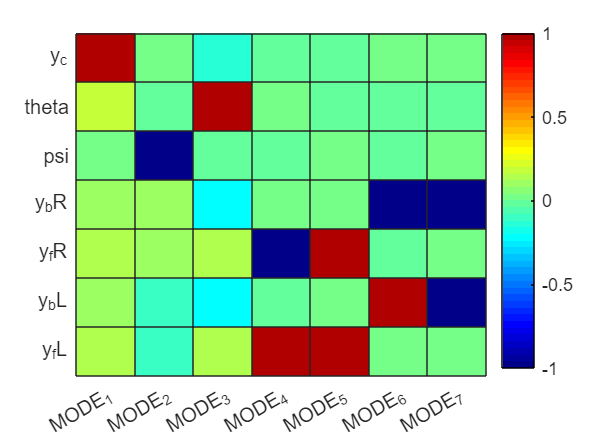

figure;
    heatmap( ("MODE_"+[1:7]), my_7dof_str_list, MAX_NORM_eVec_PHI, "Colormap", jet(50)  );

## Let's Animate the Mode shapes 

Now animate a specified MODE

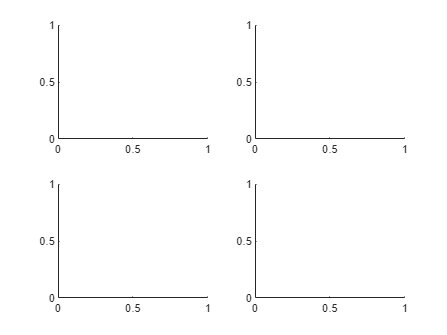

OBJ_anim = bh_7dof_car_modal_animate_CLS();  


mode_ID =  2;

OBJ_anim.animate(mode_table, mode_ID)

Unrecognized function or variable 'mode_table'.

# **Next steps:**

In the previous sections we derived the equations of motion for the 7-dof car model  These ODEs had the familiar form:

- $M\ldotp \ddot{X} \;+\;C\ldotp \dot{X} \;+\;K\ldotp X\;=\;F$     where   $X\in R^{\;7\times 1}$     and       $X^T =\left\lbrack \begin{array}{ccccccc}
y_c  & \theta  & \psi  & y_{\mathrm{bR}}  & y_{\mathrm{fR}}  & y_{\mathrm{bL}}  & y_{\mathrm{fL}} 
\end{array}\right\rbrack$

We also converted the $M,C,K,F$ matrices into Simulink blocks.  These Simulink blocks can then be used inside a Simulink model.  We've already copied these blocks into the Simulink file [`bh_COMPONENT_model_7dof_car_HAND.slx`](matlab:  open bh_COMPONENT_model_7dof_car_HAND.slx) .  

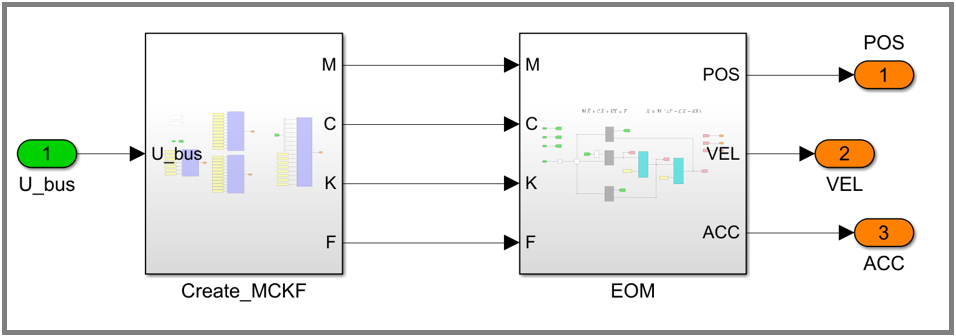

So ? - So our **next step** is to simulate these Brain derived equations of motion and explore how the dynamics of the car system respond to different types of excitation.

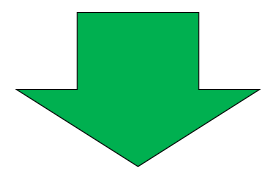

- In the file [`DEMO_02_bh_7dof_launch_sim_modal.mlx`](matlab:  edit DEMO_02_bh_7dof_launch_sim_modal.mlx) we'll explore the significance of the car's MODAL frequencies - specifically what happens when we excite the car at/near these MODAL frequencies.

- In the file [`DEMO_03_bh_7dof_launch_sim_humps.mlx`](matlab:  edit DEMO_03_bh_7dof_launch_sim_humps.mlx) we'll explore how the car dynamics respond when we excite the car using a road profile made up of a series of speed humps

# **Local Subfunctions only beyond this point**

Replace the symbolic symbols with NUMERIC values

function [M,C,K] = LOC_get_MCK(M_sym, C_sym, K_sym, OBJ_car_params)

    syms L_b  L_f    L_R   L_L
    syms  m_c    I_cZ    I_cX
    syms  m_bR   m_fR    m_bL    m_fL
    syms  k_bR   k_fR    k_bL    k_fL
    syms  c_bR   c_fR    c_bL    c_fL
    syms  k_bRG  k_fRG   k_bLG   k_fLG
    syms  c_bRG  c_fRG   c_bLG   c_fLG
    
    the_sym_list = [ L_b,    L_f,     L_R,     L_L,   ...
                     m_c,    I_cZ,    I_cX,           ... 
                     m_bR,   m_fR,    m_bL,    m_fL,  ...
                     k_bR,   k_fR,    k_bL,    k_fL,  ...
                     c_bR,   c_fR,    c_bL,    c_fL,  ...
                     k_bRG,  k_fRG,   k_bLG,   k_fLG, ...
                     c_bRG,  c_fRG,   c_bLG,   c_fLG      ];
    
    the_value_list = zeros(size(the_sym_list));
    
    for kk=1:length(the_sym_list)
        NAME                = string(  the_sym_list(kk)  );
        the_value_list(kk)  = OBJ_car_params.car_tab{NAME, "Value"};
    end
    
    M = subs(M_sym, the_sym_list, the_value_list);
    C = subs(C_sym, the_sym_list, the_value_list);
    K = subs(K_sym, the_sym_list, the_value_list);  
    
    M = double(M);
    C = double(C);
    K = double(K);

end